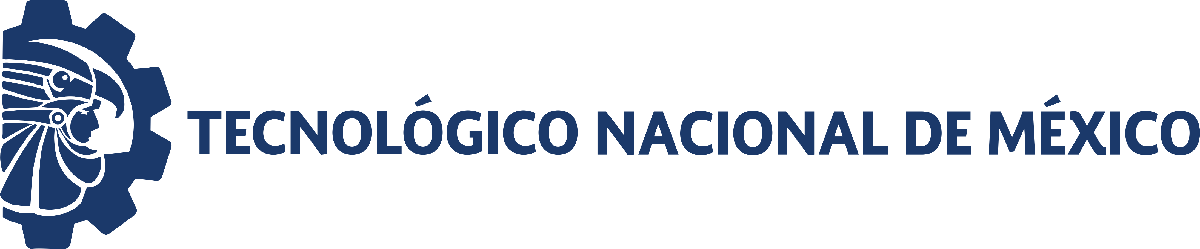                                                      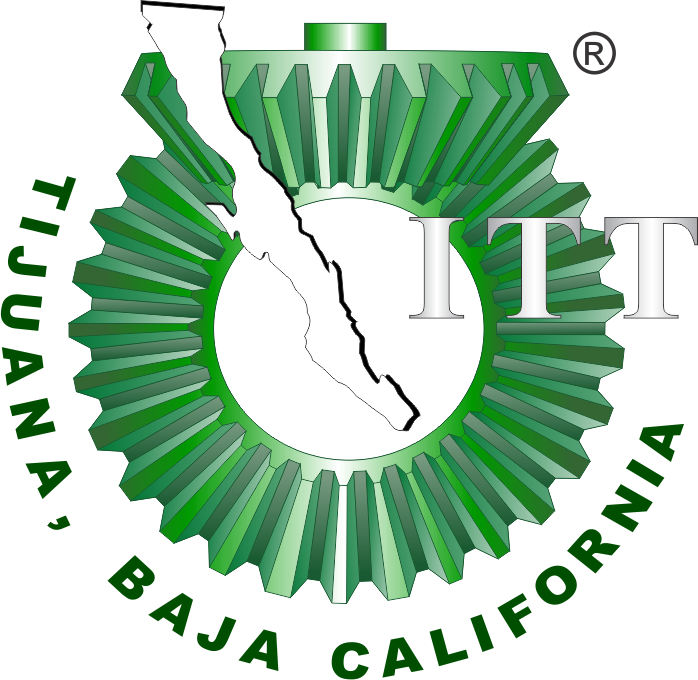

**Departamento de Ingeniería Eléctrica y Electrónica**

**Ingeniería Biomédica**

## Datos de la asignatura

Carrera: **Residencia Profesional**

Asignatura: **Biología de Sistemas**

Alumno: **Alberto Ismael Velazco Guerrero**

Número de control: **19212444**

Correo institucional: **alberto.velazco193@tectijuana.edu.mx**

Profesor: **Dr. Paul Antonio Valle Trujillo**

Correo: **paul.valle@tectijuana.edu.mx **

# **Modelo matemático de células CAR-T duales para suprimir el cáncer de mama**

Se presenta un modelo matemático basado en el desarrollado por O. León-Triana, A. Pérez-Martínez, M. Ramírez-Orellana, y V. M. Pérez-García en el 2021. El modelo propuesto describe la competencia entre las células CAR-T y las células tumorales, teniendo en cuenta su capacidad inmunosupresora. Las Ecuaciones siguientes ecuaciones representan las interacciones que existen entre las células CAR-T, las células B y las células tumorales,


$$\frac{d\bar{C}}{dt} = \frac{\rho _{\bar{C}}\bar{C}B}{g_{B}+B}-\frac{1}{\tau _{C}}\bar{C}-k\bar{C}+\varphi _{\bar{C}} \\
\frac{dB}{dt} =-\alpha _{B}B\bar{C}-\frac{1}{\tau _{B}}B \\
\frac{dC}{dt}=k\bar{C}+ \frac{\rho _{C}CT}{g_{T}+T}-\frac{\alpha _{1}CT}{g_{C}+C}-%
\frac{1}{\tau _{C}}C\\
\frac{dT}{dt}=\rho _{T}T-\alpha _{2}CT$$


donde $\varphi_{\bar{C} }$ es la nueva variable incorporada al sistema y representa la aplicación de células CAR-T regularmente. La primera ecuación fue modificada para representar el efecto de la aplicación de células CAR-T duales en el paciente.

## **Referencia**

O. León-Triana, A. Pérez-Martínez, M. Ramírez-Orellana, and V. M. Pérez-García, ''Dual-target CARTs with on-and off-tumour activity may override immune suppression in solid cancers: A mathematical proof of concept,'' *Cancers*, vol. 13, no. 4, p. 703, 2021, [https://doi.org/10.3390/cancers13040703.](https://doi.org/10.3390/cancers13040703.)

## Modelo matemático de células CAR-T duales para suprimir el cáncer de mama

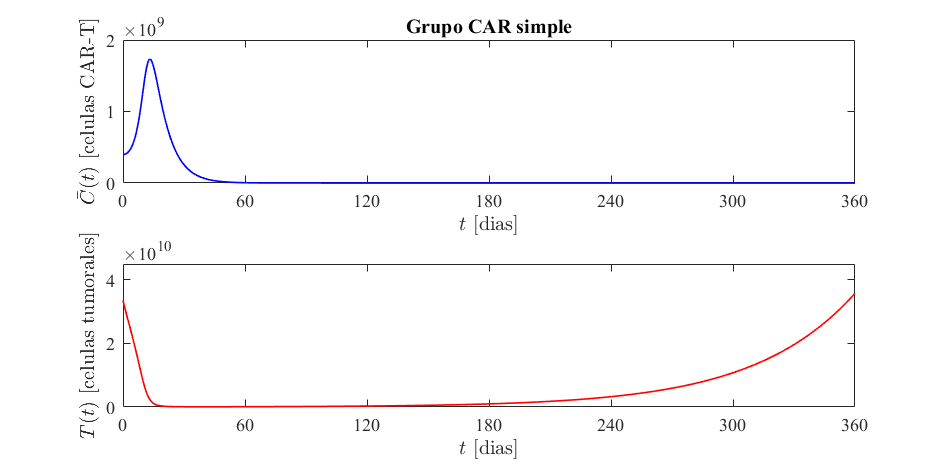

%C(t) = x(t) & C(0)=x(0)
%T(t) = y(t) & T(0)=y(0)

%Modelo I (Modelo de dos ecuaciones)
%Representa la interacción entre células CAR-T y células tumorales dentro
%del tumor
x0 = 4E8; y0 = 3.35E10; alfa1 = 0.04;

tauC = 7; rhoC = 0.9; rhoT =  0.02; 
alfa2 = 2.5E-10; gT = 10^10; gC = 2E9; 

P = [tauC,rhoC,rhoT,alfa2,gT,gC];
dt=1E-4;

[t,x,y] = digitalTwinI(x0,y0,alfa1,P,dt,360);

%Gráfica del modelo de dos ecuaciones
plotdataRIIA(t,x,y)

## **Modelo matemático de células CAR-T duales para suprimir el cáncer de mama**

### **Modelo aplicando un tratamiento constante**

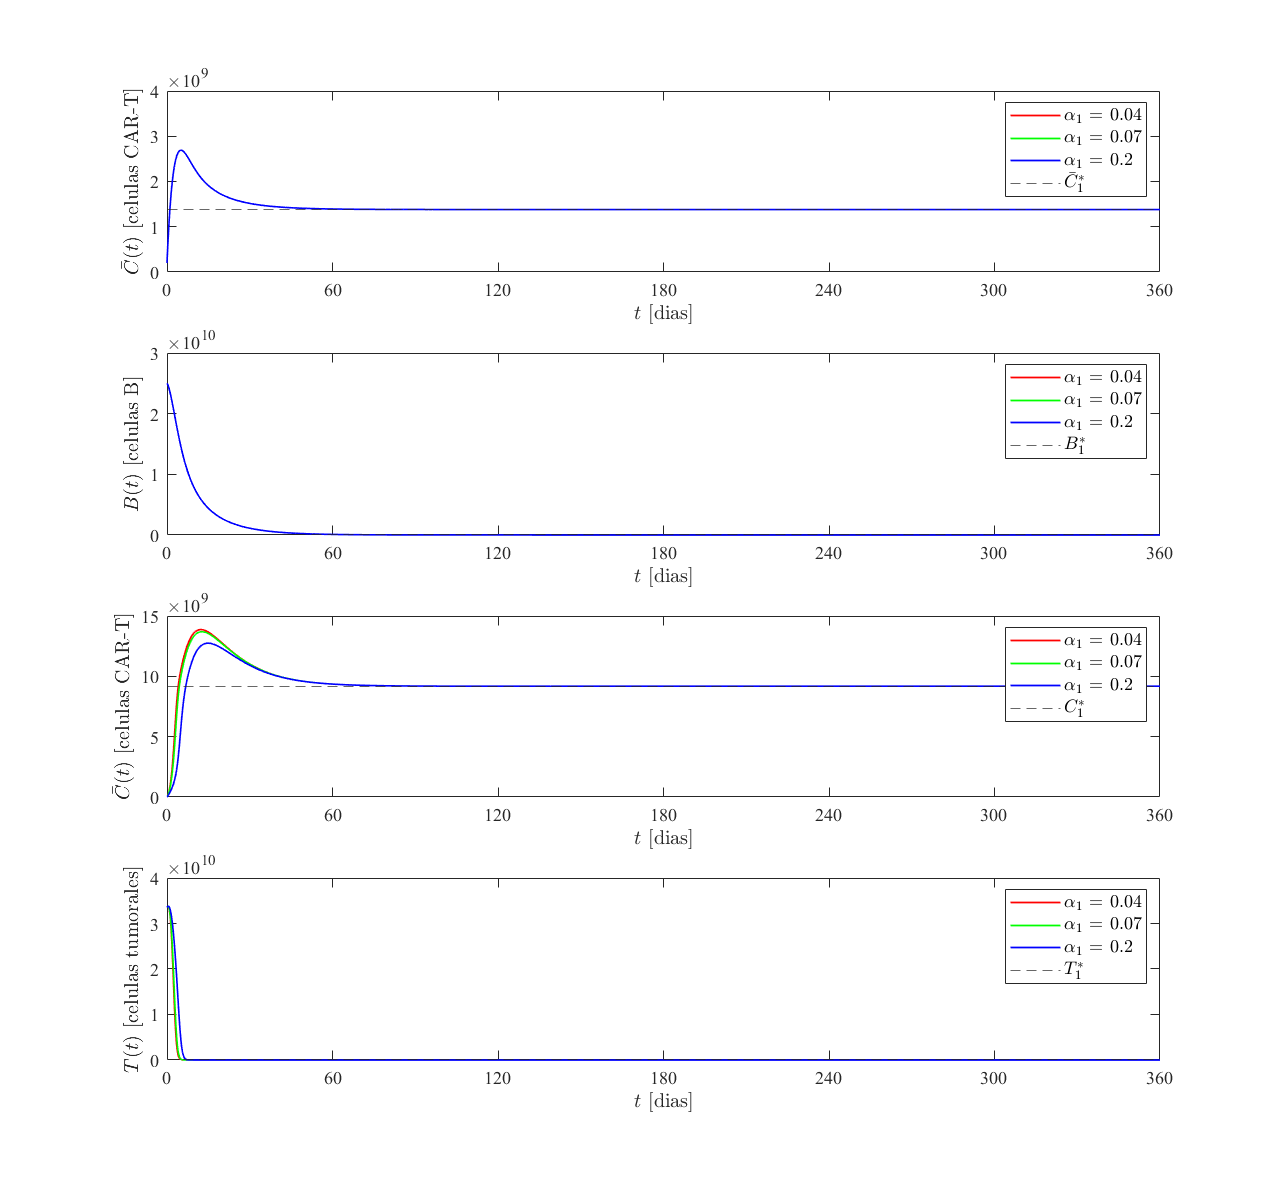

%Cbar(t) = x(t) & Cbar(0)=x(0) 
%B(t) = y(t) & B(0)=y(0)
%C(t) = z(t) & C(0)=z(0)
%T(t) = w(t) & T(0)=w(0)

%Modelo II
clear
x0 = 2E8; y0 = 2.5E10; 
z0 = 0; w0 = 3.35E10;  
alfa1 = [0.04, 0.07, 0.2];

tauC = 7; rhoC = 0.9; rhoCbar = 0.9; rhoT = 0.038; %1/65; Antiguo valor del modelo 
alfa2 = 2.5E-10; gT = 1E10; gC = 2E9; gB = 1E10; 
q = 0.95; alfaB = 4.5E-11; tauB = 60;

varphi = 1.1*(1/q*tauB)*(rhoT/(alfa2*tauC)-rhoC); %Variable agregada al modelo

P = [tauC,rhoC,rhoCbar,rhoT,alfa2,gT,gC,gB,...
    q,alfaB,tauB];
dt=1E-4;

paraX = cell(1,length(alfa1));
paraY = cell(1,length(alfa1));
paraZ = cell(1,length(alfa1));
paraW = cell(1,length(alfa1));

for i = 1:length(alfa1)
    [t,x,y,z,w] = digitalTwinII(x0,y0,z0,w0,alfa1(i),P,dt,360,varphi);
    paraX{i} = x;
    paraY{i} = y;
    paraZ{i} = z;
    paraW{i} = w;
end

equilibrioCbar = (tauC*varphi)/(q*tauC+1);
equilibrioB = 0;
equilibrioC = (q*tauC^2*varphi)/(q*tauC+1);
equilibrioT = 0;

%Graficas del modelo con punto de equilibrio
plotdataRIIB(t,paraX,paraY,paraZ,paraW,equilibrioCbar,equilibrioB,equilibrioC,equilibrioT)

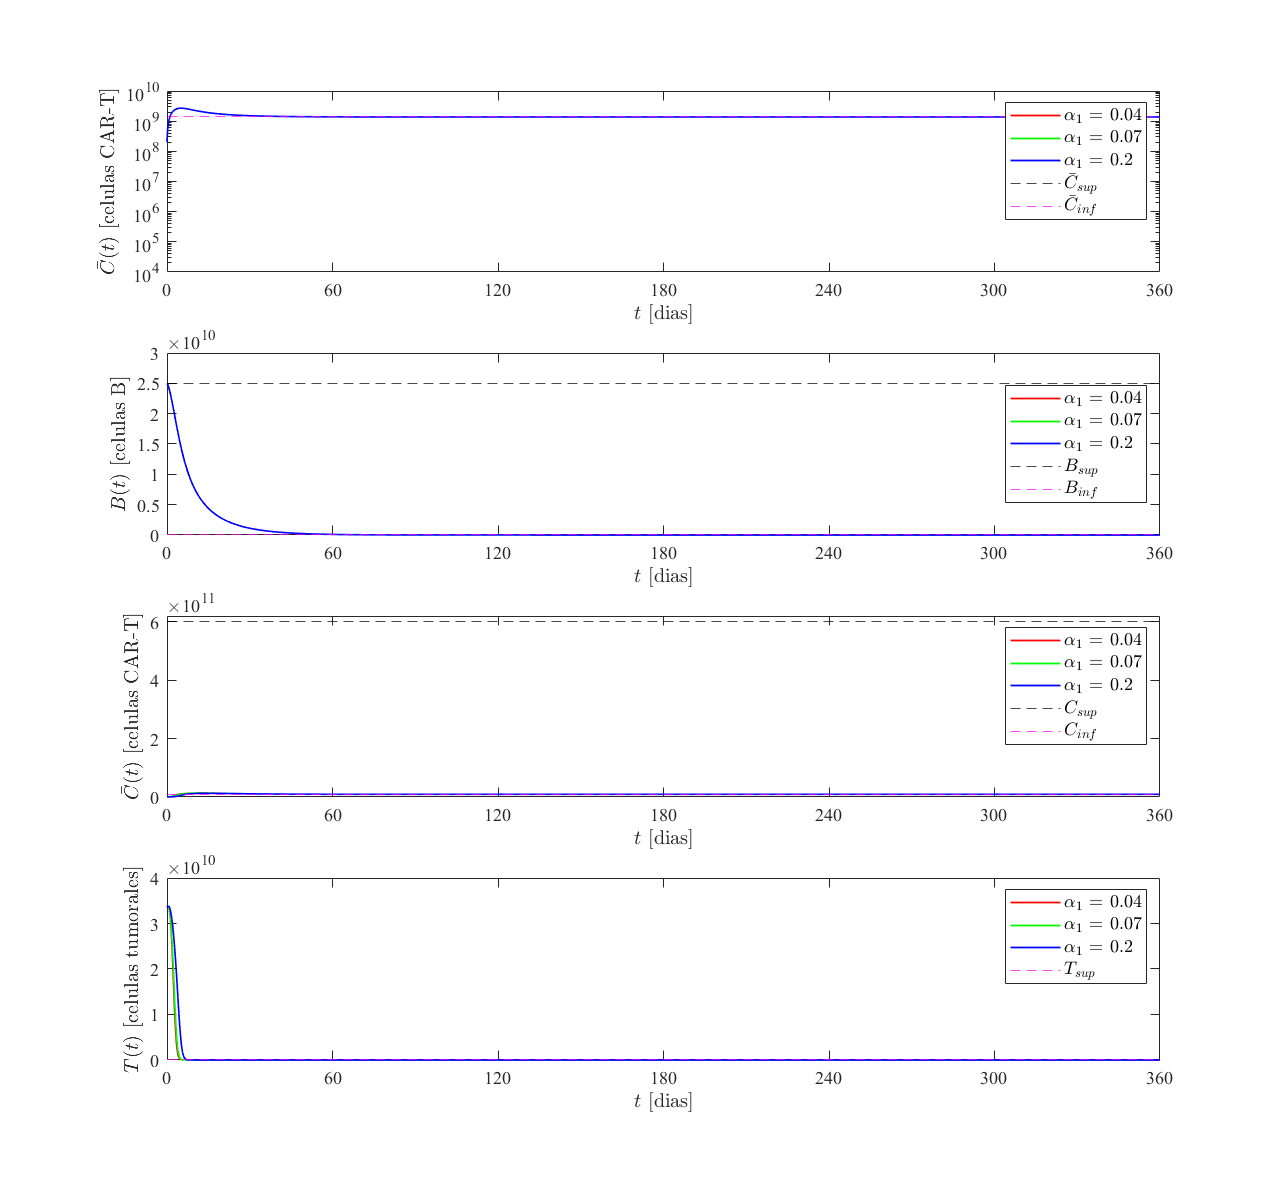

%name = 'graficasconequilibrios';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')

Cbarinf = varphi/(1/tauC+q);
Cbarsup = tauB*varphi;
Binf = 0;
Bsup = y0;
Cinf = tauC*q*Cbarinf;
Csup = tauC*(q*Cbarsup+rhoC);
Tinf = 0;

%Graficar del modelo infimos y supremos
plotdataRIIC(t,paraX,paraY,paraZ,paraW,Cbarinf,Cbarsup,Binf,Bsup,Cinf,Csup,Tinf)

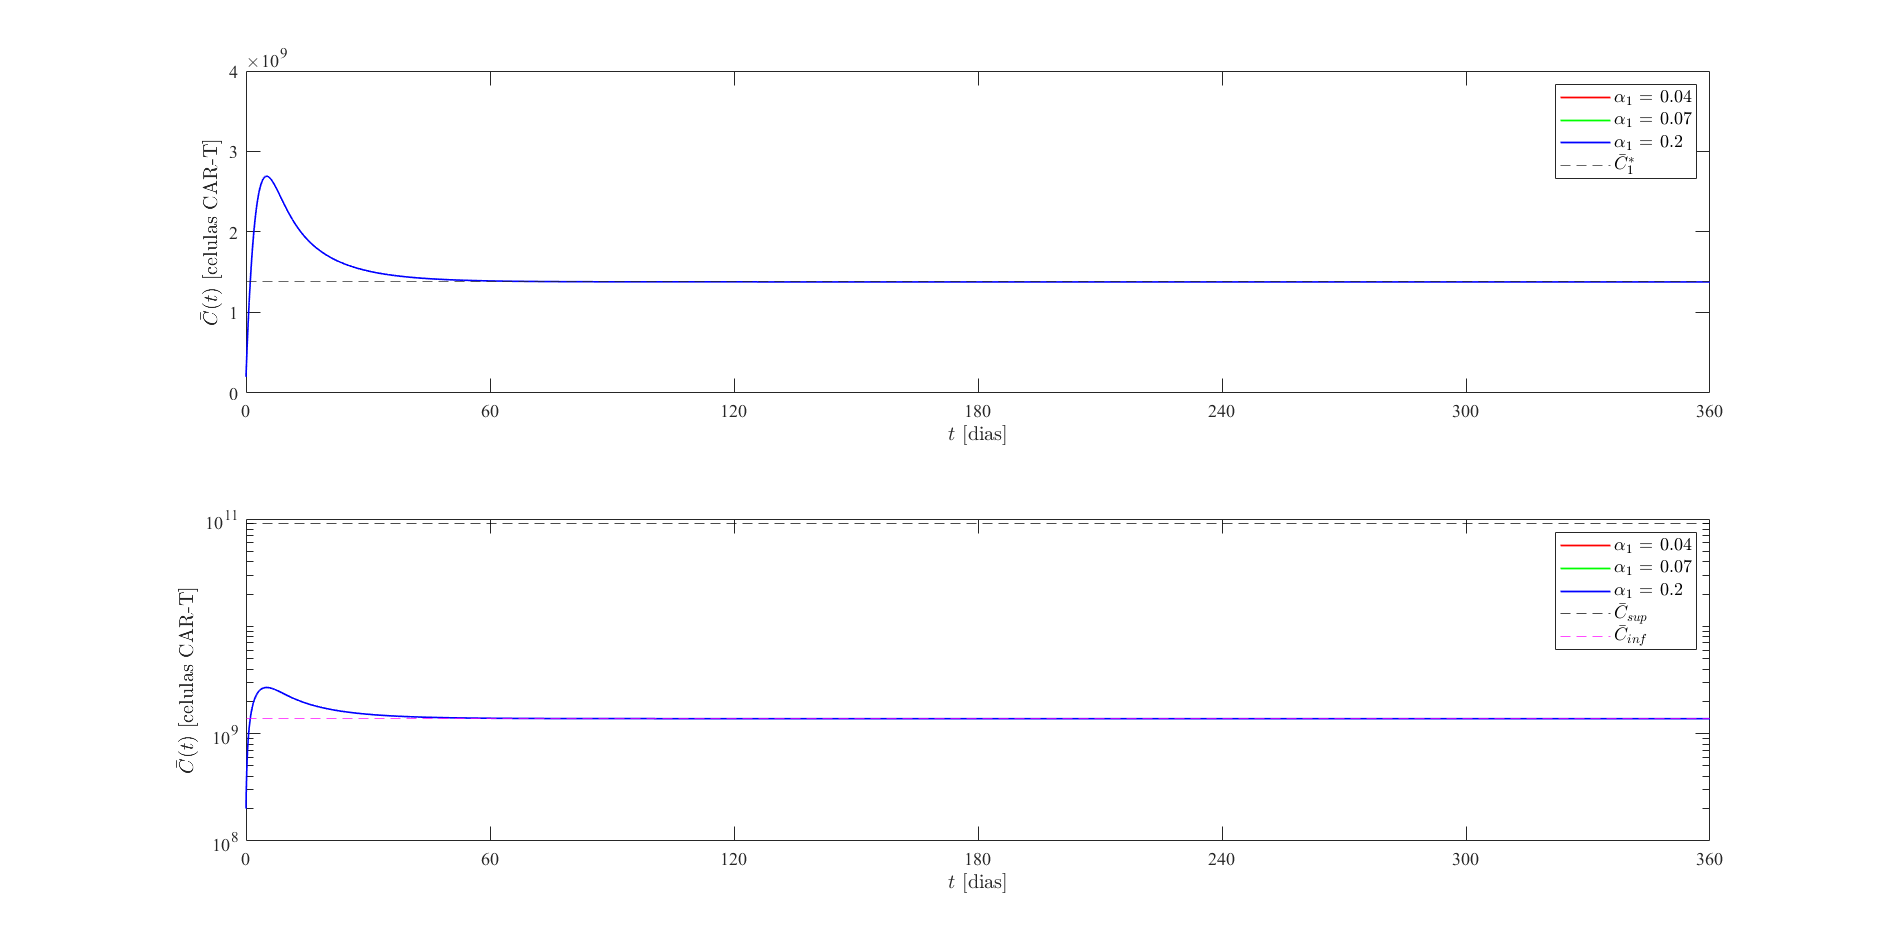

%name = 'graficasLCCI';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')

%Graficas individuales de los grupos celulares

plotdataIndividualesX(t,paraX,Cbarinf,Cbarsup,equilibrioCbar)
%name = 'graficasCbar';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')
%exportgraphics(gcf,[name,'.png'])

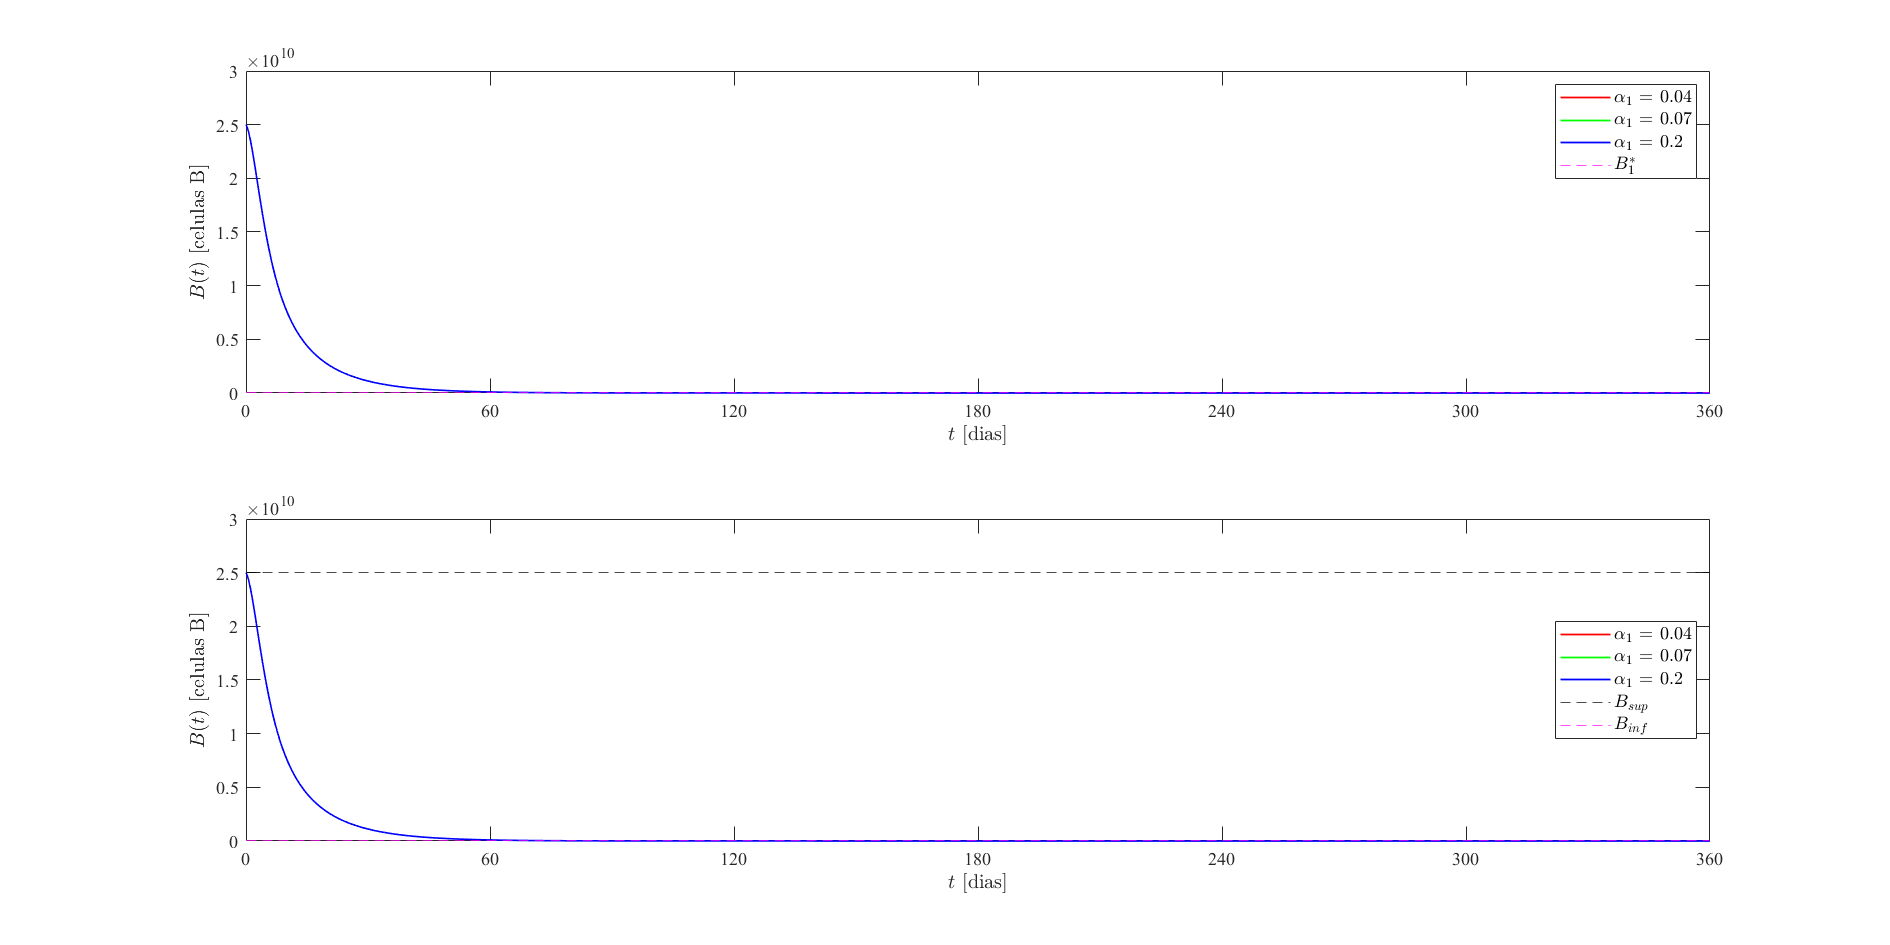


plotdataIndividualesY(t,paraY,Binf,Bsup,equilibrioB)
%name = 'graficasB';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')
%exportgraphics(gcf,[name,'.png'])

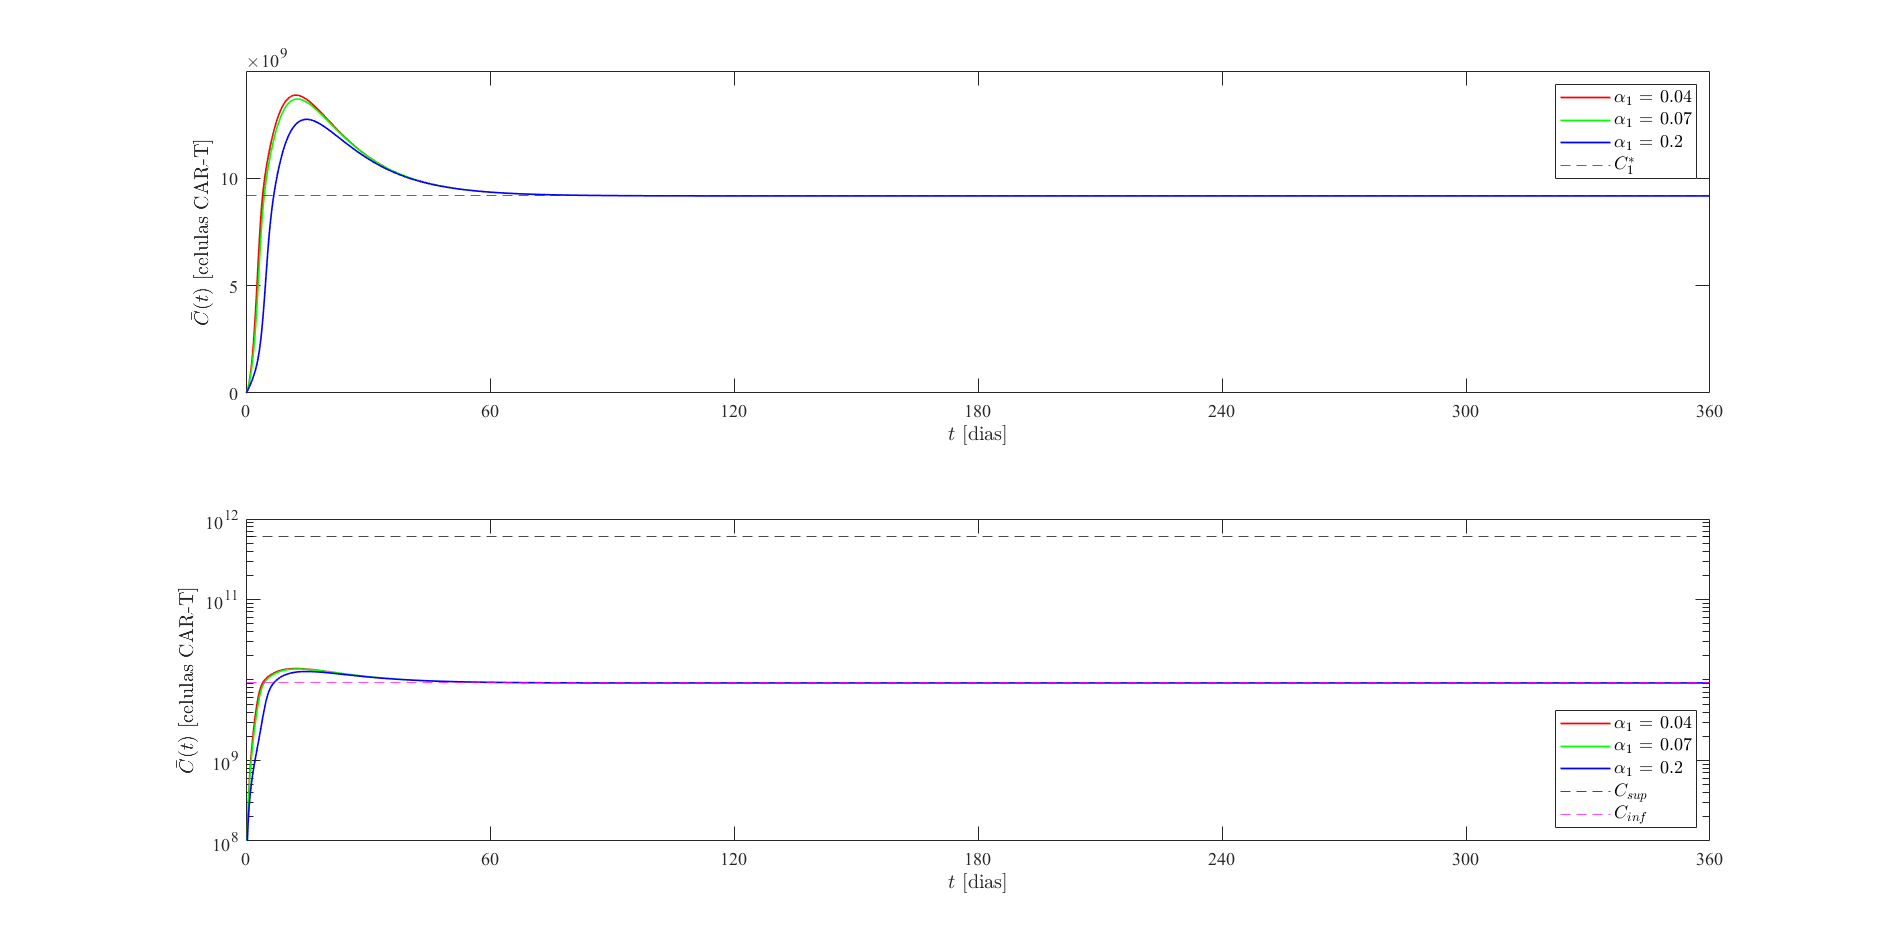


plotdataIndividualesZ(t,paraZ,Cinf,Csup,equilibrioC)
%name = 'graficasC';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')
%exportgraphics(gcf,[name,'.png'])

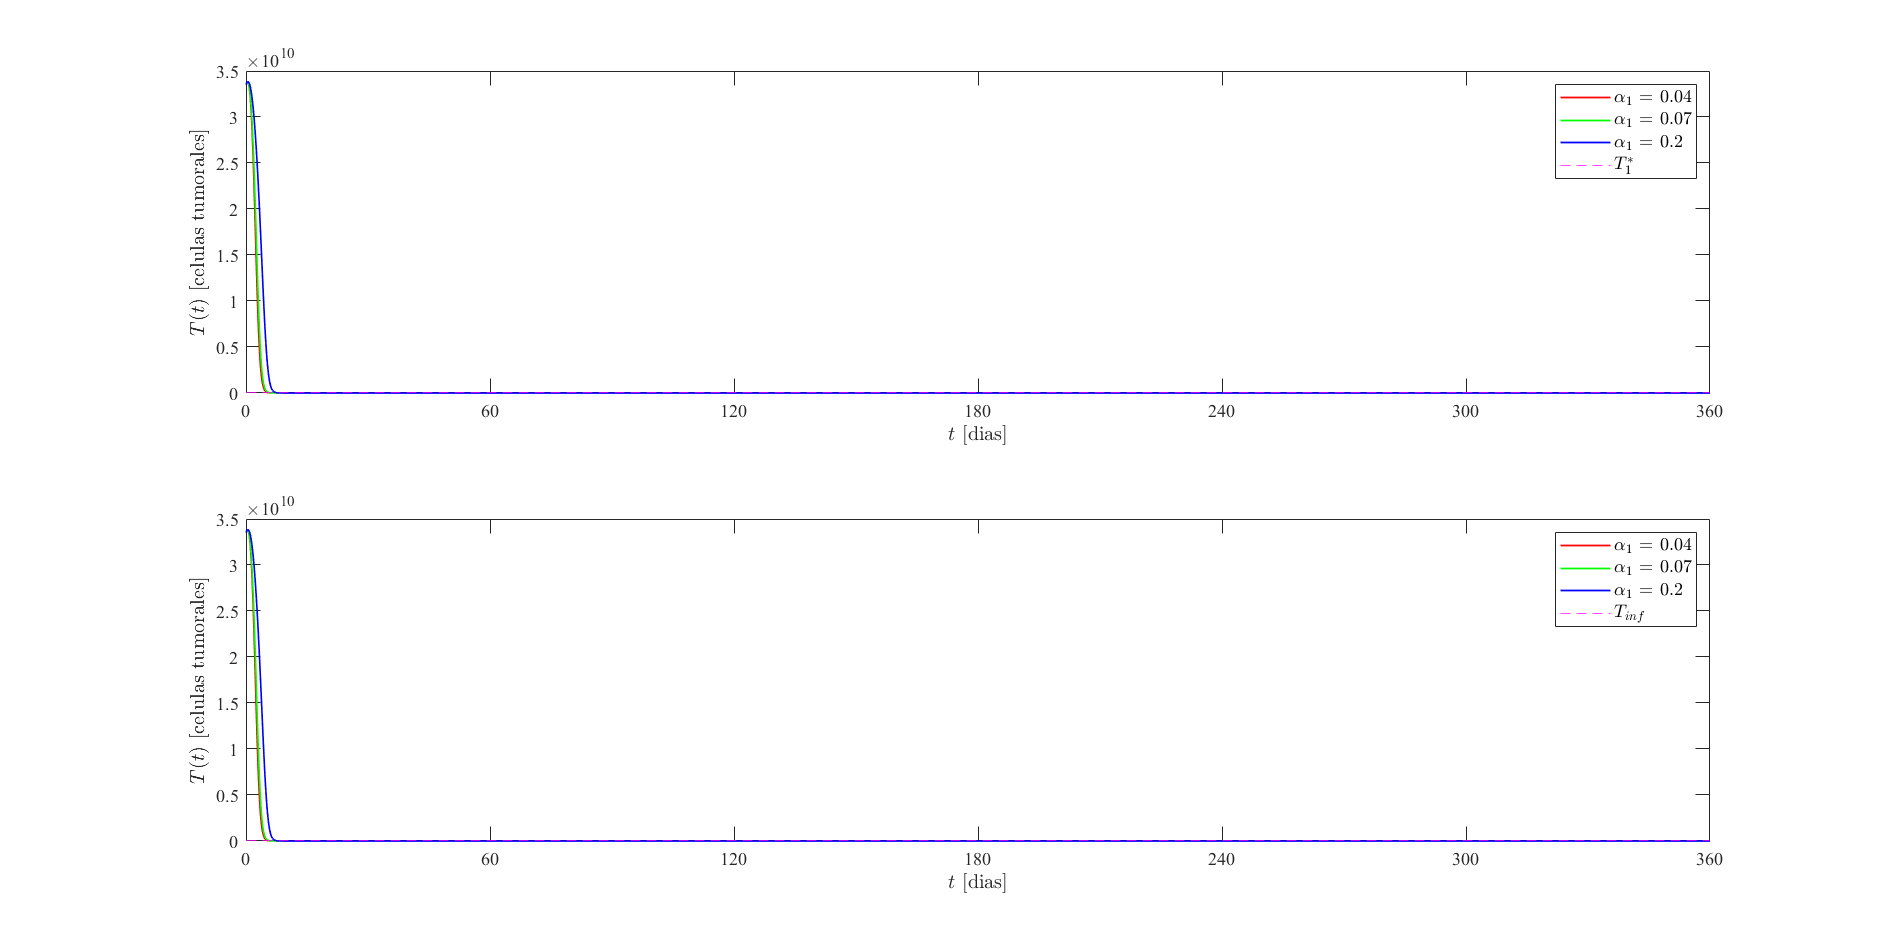


plotdataIndividualesW(t,paraW,Tinf,equilibrioT)
%name = 'graficasT';
%exportgraphics(gcf,[name,'.pdf'],'ContentType','vector')
%exportgraphics(gcf,[name,'.png'])

### **Modelo aplicando un protocolo de tratamiento**

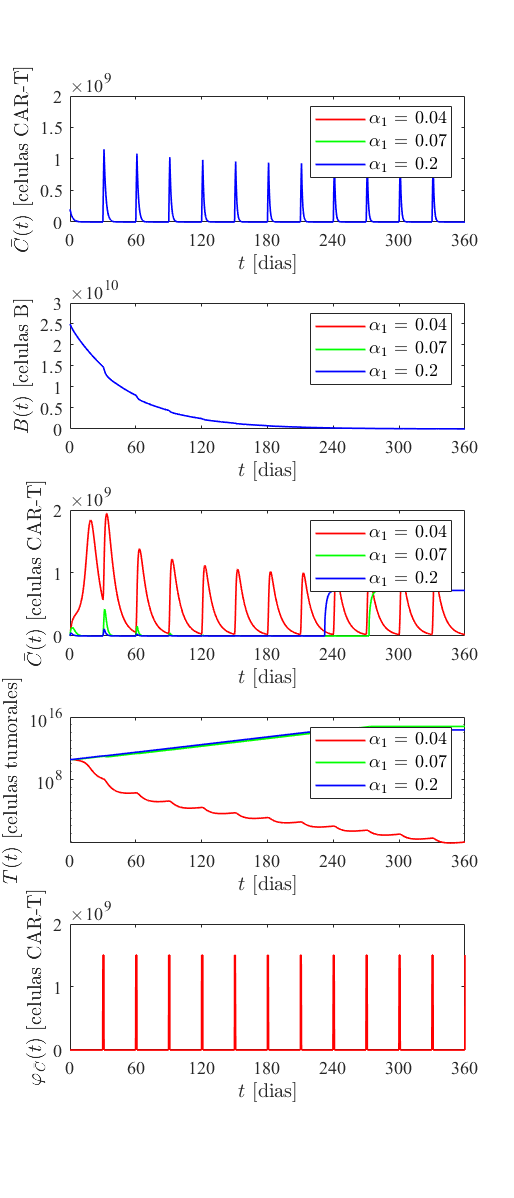

%Cbar(t) = x(t) & Cbar(0)=x(0) 
%B(t) = y(t) & B(0)=y(0)
%C(t) = z(t) & C(0)=z(0)
%T(t) = w(t) & T(0)=w(0)

%Modelo II con protocolo de tratamiento
clear
x0 = 2E8; y0 = 2.5E10; 
z0 = 0; w0 = 3.35E10;  
alfa1 = [0.04, 0.07, 0.2];

tauC = 7; rhoC = 0.9; rhoCbar = 0.9; rhoT = 0.038; %1/65 Antiguo valor del modelo 
alfa2 = 2.5E-10; gT = 1E10; gC = 2E9; gB = 1E10; 
q = 0.95; alfaB = 4.5E-11; tauB = 60;

varphi = 1.1*(1/q*tauB)*(rhoT/(alfa2*tauC)-rhoC); %Variable agregada al modelo

dias = 30; %Dias en que se aplicará el tratamiento (Modificable segun el periodo de tratamiento
% que se desea ser aplicado)
          
P = [tauC,rhoC,rhoCbar,rhoT,alfa2,gT,gC,gB,...
    q,alfaB,tauB];
dt=1E-4;

paraX = cell(1,length(alfa1));
paraY = cell(1,length(alfa1));
paraZ = cell(1,length(alfa1));
paraW = cell(1,length(alfa1));

for i = 1:length(alfa1)
    [t,x,y,z,w,varphi_valores] = digitalTwinIII(x0,y0,z0,w0,alfa1(i),P,dt,360,varphi,dias);
    paraX{i} = x;
    paraY{i} = y;
    paraZ{i} = z;
    paraW{i} = w;
end

%Gráfica de soluciones a la administración de un prótocolo de tratamiento
plotSoluciones(t,paraX,paraY,paraZ,paraW,varphi_valores)

%name = sprintf('graficas_%d_CbarB',dias);
%exportgraphics(gcf,[name,'.png'],'ContentType','vector')
%exportgraphics(gcf,[name,'.png'])

## Matriz Jacobiana y equilibrios para Modelo Mejorado

clear 
syms x y z w alfa1 tauC rhoC rhoCbar rhoT alfa2 gT gC gB q alfaB tauB varphi

### Matriz Jacobiana

dx = (rhoC * x * y) / (gB + y) - (x / tauC) - q * x + varphi;
dy = -alfaB * y * x - (y / tauB);
dz = q * x + (rhoC * z * w) / (gT + w) - (alfa1 * z * w) / (gC + z) - (z / tauC);
dw = rhoT * w - alfa2 * z * w;

J = simplify(jacobian([dx,dy,dz,dw],[x,y,z,w])); disp(J)

$$\left(\begin{array}{cccc} \frac{\mathrm{rhoC}\,y}{\mathrm{gB}+y}-\frac{1}{\mathrm{tauC}}-q & \frac{\mathrm{gB}\,\mathrm{rhoC}\,x}{{\left(\mathrm{gB}+y\right)}^{2}} & 0 & 0\\ -\mathrm{alfaB}\,y & -\mathrm{alfaB}\,x-\frac{1}{\mathrm{tauB}} & 0 & 0\\ q & 0 & \frac{\mathrm{rhoC}\,w}{\mathrm{gT}+w}-\frac{{\mathrm{alfa}}_{1}\,w}{\mathrm{gC}+z}-\frac{1}{\mathrm{tauC}}+\frac{{\mathrm{alfa}}_{1}\,w\,z}{{\left(\mathrm{gC}+z\right)}^{2}} & \frac{\mathrm{rhoC}\,z}{\mathrm{gT}+w}-\frac{{\mathrm{alfa}}_{1}\,z}{\mathrm{gC}+z}-\frac{\mathrm{rhoC}\,w\,z}{{\left(\mathrm{gT}+w\right)}^{2}}\\ 0 & 0 & -{\mathrm{alfa}}_{2}\,w & \mathrm{rhoT}-{\mathrm{alfa}}_{2}\,z \end{array}\right)$$

### Equlibrios simbólicos

dx = (rhoC * x * y) / (gB + y) - (x / tauC) - q * x + varphi;
dy = -alfaB * y * x - (y / tauB);
dz = q * x + (rhoC * z * w) / (gT + w) - (alfa1 * z * w) / (gC + z) - (z / tauC);
dw = rhoT * w - alfa2 * z * w;
equilibra = solve([dx,dy,dz,dw],[x,y,z,w]);

for i = 1:6
    xe(i,1) = simplify(equilibra.x(i));
    ye(i,1) = simplify(equilibra.y(i));
    ze(i,1) = simplify(equilibra.z(i));
    we(i,1) = simplify(equilibra.w(i));

    disp(['Equilibirum ',num2str(i),':'])

    disp(['x',num2str(i),' = ',char(xe(i,1))]);
    disp(['y',num2str(i),' = ',char(ye(i,1))]);
    disp(['z',num2str(i),' = ',char(ze(i,1))]);
    disp(['w',num2str(i),' = ',char(we(i,1))]);
    
    fprintf('\n')
end

Equilibirum 1:


x1 = -1/(alfaB*tauB)


y1 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1)


z1 = rhoT/alfa2


w1 = -((alfaB^2*rhoT^4*tauB^2 + alfa2^4*gC^2*q^2*tauC^2 + alfa2^2*q^2*rhoT^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoT^2*tauB^2 + alfaB^2*rhoC^2*rhoT^4*tauB^2*tauC^2 + 2*alfa2*alfaB^2*gC*rhoT^3*tauB^2 + 2*alfa2^3*gC*q^2*rhoT*tauC^2 - 2*alfaB^2*rhoC*rhoT^4*tauB^2*tauC + 2*alfa2*alfaB*q*rhoT^3*tauB*tauC + 4*alfa2^2*alfaB*gC*q*rhoT^2*tauB*tauC + 2*alfa2^3*alfaB*gC^2*q*rhoT*tauB*tauC - 2*alfa2*alfaB*q*rhoC*rhoT^3*tauB*tauC^2 - 2*alfa2^2*alfaB^2*gC^2*rhoC*rhoT^2*tauB^2*tauC + 2*alfa2*alfaB^2*gC*rhoC^2*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2*alfaB^2*gT*rhoT^3*tauB^2*tauC - 4*alfa2*alfaB^2*gC*rhoC*rhoT^3*tauB^2*tauC + alfa1^2*alfa2^2*alfaB^2*gT^2*rhoT^2*tauB^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoC^2*rhoT^2*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoT^2*tauB^2*tauC - 2*alfa1*alfa2*alfaB^2*gT*rhoC*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB*gT*q*rhoT^2*tauB*tauC^2 - 4*alfa2^2*alfaB*gC*q*rhoC*rhoT^2*tauB*tauC^2 - 2*alfa2^3*alfaB*gC^2*q*rhoC*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^3*alfaB*gC*gT*q*rhoT*tauB*ta

Equilibirum 2:


x2 = (tauC*varphi)/(q*tauC + 1)


y2 = 0


z2 = rhoT/alfa2


w2 = ((rhoT^4 + 2*q*rhoT^4*tauC - 2*rhoC*rhoT^4*tauC + alfa2^2*gC^2*rhoT^2 + q^2*rhoT^4*tauC^2 + rhoC^2*rhoT^4*tauC^2 + 2*alfa2*gC*rhoT^3 + 2*q*rhoC^2*rhoT^4*tauC^3 - 2*q^2*rhoC*rhoT^4*tauC^3 + q^2*rhoC^2*rhoT^4*tauC^4 - 4*q*rhoC*rhoT^4*tauC^2 + alfa1^2*alfa2^2*gT^2*rhoT^2*tauC^2 - 2*alfa2*q*rhoT^3*tauC^2*varphi + alfa2^2*gC^2*q^2*rhoT^2*tauC^2 + alfa2^2*gC^2*rhoC^2*rhoT^2*tauC^2 + alfa2^4*gC^2*q^2*tauC^4*varphi^2 + alfa2^2*q^2*rhoT^2*tauC^4*varphi^2 + 2*alfa2^2*gC^2*q*rhoT^2*tauC + 2*alfa2*gC*q^2*rhoT^3*tauC^2 - 2*alfa2^2*gC^2*rhoC*rhoT^2*tauC + 2*alfa2*gC*rhoC^2*rhoT^3*tauC^2 - 2*alfa2*q^2*rhoT^3*tauC^3*varphi - 2*alfa1*alfa2*gT*rhoT^3*tauC + 4*alfa2*gC*q*rhoT^3*tauC - 4*alfa2*gC*rhoC*rhoT^3*tauC + 4*alfa2*gC*q*rhoC^2*rhoT^3*tauC^3 - 4*alfa2*gC*q^2*rhoC*rhoT^3*tauC^3 - 4*alfa2^2*gC*q*rhoT^2*tauC^2*varphi - 2*alfa2^3*gC^2*q*rhoT*tauC^2*varphi + alfa1^2*alfa2^2*gT^2*q^2*rhoT^2*tauC^4 + 2*alfa2*q^2*rhoC*rhoT^3*tauC^4*varphi + alfa2^2*gC^2*q^2*rhoC^2*rhoT^2*tauC^4 - 4*alfa2^2*gC^2*q*rhoC

Equilibirum 3:


x3 = (tauC*varphi)/(q*tauC + 1)


y3 = 0


z3 = (q*tauC^2*varphi)/(q*tauC + 1)


w3 = 0


Equilibirum 4:


x4 = -1/(alfaB*tauB)


y4 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1)


z4 = rhoT/alfa2


w4 = -(alfaB*rhoT^2*tauB - (alfaB^2*rhoT^4*tauB^2 + alfa2^4*gC^2*q^2*tauC^2 + alfa2^2*q^2*rhoT^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoT^2*tauB^2 + alfaB^2*rhoC^2*rhoT^4*tauB^2*tauC^2 + 2*alfa2*alfaB^2*gC*rhoT^3*tauB^2 + 2*alfa2^3*gC*q^2*rhoT*tauC^2 - 2*alfaB^2*rhoC*rhoT^4*tauB^2*tauC + 2*alfa2*alfaB*q*rhoT^3*tauB*tauC + 4*alfa2^2*alfaB*gC*q*rhoT^2*tauB*tauC + 2*alfa2^3*alfaB*gC^2*q*rhoT*tauB*tauC - 2*alfa2*alfaB*q*rhoC*rhoT^3*tauB*tauC^2 - 2*alfa2^2*alfaB^2*gC^2*rhoC*rhoT^2*tauB^2*tauC + 2*alfa2*alfaB^2*gC*rhoC^2*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2*alfaB^2*gT*rhoT^3*tauB^2*tauC - 4*alfa2*alfaB^2*gC*rhoC*rhoT^3*tauB^2*tauC + alfa1^2*alfa2^2*alfaB^2*gT^2*rhoT^2*tauB^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoC^2*rhoT^2*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoT^2*tauB^2*tauC - 2*alfa1*alfa2*alfaB^2*gT*rhoC*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB*gT*q*rhoT^2*tauB*tauC^2 - 4*alfa2^2*alfaB*gC*q*rhoC*rhoT^2*tauB*tauC^2 - 2*alfa2^3*alfaB*gC^2*q*rhoC*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^3*alfaB*

Equilibirum 5:


x5 = -1/(alfaB*tauB)


y5 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1)


z5 = -(q*tauC)/(alfaB*tauB)


w5 = 0


Equilibirum 6:


x6 = (tauC*varphi)/(q*tauC + 1)


y6 = 0


z6 = rhoT/alfa2


w6 = -((rhoT^4 + 2*q*rhoT^4*tauC - 2*rhoC*rhoT^4*tauC + alfa2^2*gC^2*rhoT^2 + q^2*rhoT^4*tauC^2 + rhoC^2*rhoT^4*tauC^2 + 2*alfa2*gC*rhoT^3 + 2*q*rhoC^2*rhoT^4*tauC^3 - 2*q^2*rhoC*rhoT^4*tauC^3 + q^2*rhoC^2*rhoT^4*tauC^4 - 4*q*rhoC*rhoT^4*tauC^2 + alfa1^2*alfa2^2*gT^2*rhoT^2*tauC^2 - 2*alfa2*q*rhoT^3*tauC^2*varphi + alfa2^2*gC^2*q^2*rhoT^2*tauC^2 + alfa2^2*gC^2*rhoC^2*rhoT^2*tauC^2 + alfa2^4*gC^2*q^2*tauC^4*varphi^2 + alfa2^2*q^2*rhoT^2*tauC^4*varphi^2 + 2*alfa2^2*gC^2*q*rhoT^2*tauC + 2*alfa2*gC*q^2*rhoT^3*tauC^2 - 2*alfa2^2*gC^2*rhoC*rhoT^2*tauC + 2*alfa2*gC*rhoC^2*rhoT^3*tauC^2 - 2*alfa2*q^2*rhoT^3*tauC^3*varphi - 2*alfa1*alfa2*gT*rhoT^3*tauC + 4*alfa2*gC*q*rhoT^3*tauC - 4*alfa2*gC*rhoC*rhoT^3*tauC + 4*alfa2*gC*q*rhoC^2*rhoT^3*tauC^3 - 4*alfa2*gC*q^2*rhoC*rhoT^3*tauC^3 - 4*alfa2^2*gC*q*rhoT^2*tauC^2*varphi - 2*alfa2^3*gC^2*q*rhoT*tauC^2*varphi + alfa1^2*alfa2^2*gT^2*q^2*rhoT^2*tauC^4 + 2*alfa2*q^2*rhoC*rhoT^3*tauC^4*varphi + alfa2^2*gC^2*q^2*rhoC^2*rhoT^2*tauC^4 - 4*alfa2^2*gC^2*q*rho

### Equilibrio numéricos

clear
x0 = 2E8; y0 = 2.5E10; 
z0 = 0; w0 = 3.35E10;  
alfa1_valores = [0.04, 0.07, 0.2];

tauC = 7; rhoC = 0.9; rhoCbar = 0.9; rhoT = 0.038; %1/65 Antiguo valor del modelo 
alfa2 = 2.5E-10; gT = 1E10; gC = 2E9; gB = 1E10; 
q = 0.95; alfaB = 4.5E-11; tauB = 60;

varphi = 1.1*1/q*tauB*(rhoT/(alfa2*tauC)-rhoC); %Variable agregada al modelo

for i = 1:numel(alfa1_valores)
    alfa1 = alfa1_valores(i);

    x1 = -1/(alfaB*tauB);
    y1 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1);
    z1 = rhoT/alfa2;
    w1 = -((alfaB^2*rhoT^4*tauB^2 + alfa2^4*gC^2*q^2*tauC^2 + alfa2^2*q^2*rhoT^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoT^2*tauB^2 + alfaB^2*rhoC^2*rhoT^4*tauB^2*tauC^2 + 2*alfa2*alfaB^2*gC*rhoT^3*tauB^2 + 2*alfa2^3*gC*q^2*rhoT*tauC^2 - 2*alfaB^2*rhoC*rhoT^4*tauB^2*tauC + 2*alfa2*alfaB*q*rhoT^3*tauB*tauC + 4*alfa2^2*alfaB*gC*q*rhoT^2*tauB*tauC + 2*alfa2^3*alfaB*gC^2*q*rhoT*tauB*tauC - 2*alfa2*alfaB*q*rhoC*rhoT^3*tauB*tauC^2 - 2*alfa2^2*alfaB^2*gC^2*rhoC*rhoT^2*tauB^2*tauC + 2*alfa2*alfaB^2*gC*rhoC^2*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2*alfaB^2*gT*rhoT^3*tauB^2*tauC - 4*alfa2*alfaB^2*gC*rhoC*rhoT^3*tauB^2*tauC + alfa1^2*alfa2^2*alfaB^2*gT^2*rhoT^2*tauB^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoC^2*rhoT^2*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoT^2*tauB^2*tauC - 2*alfa1*alfa2*alfaB^2*gT*rhoC*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB*gT*q*rhoT^2*tauB*tauC^2 - 4*alfa2^2*alfaB*gC*q*rhoC*rhoT^2*tauB*tauC^2 - 2*alfa2^3*alfaB*gC^2*q*rhoC*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^3*alfaB*gC*gT*q*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoC*rhoT^2*tauB^2*tauC^2)^(1/2) + alfaB*rhoT^2*tauB + alfa2*q*rhoT*tauC + alfa2^2*gC*q*tauC + alfa2*alfaB*gC*rhoT*tauB - alfaB*rhoC*rhoT^2*tauB*tauC + alfa1*alfa2*alfaB*gT*rhoT*tauB*tauC - alfa2*alfaB*gC*rhoC*rhoT*tauB*tauC)/(2*alfa1*alfa2*alfaB*rhoT*tauB*tauC);

    x2 = (tauC*varphi)/(q*tauC + 1);
    y2 = 0;
    z2 = rhoT/alfa2;
    w2 = ((rhoT^4 + 2*q*rhoT^4*tauC - 2*rhoC*rhoT^4*tauC + alfa2^2*gC^2*rhoT^2 + q^2*rhoT^4*tauC^2 + rhoC^2*rhoT^4*tauC^2 + 2*alfa2*gC*rhoT^3 + 2*q*rhoC^2*rhoT^4*tauC^3 - 2*q^2*rhoC*rhoT^4*tauC^3 + q^2*rhoC^2*rhoT^4*tauC^4 - 4*q*rhoC*rhoT^4*tauC^2 + alfa1^2*alfa2^2*gT^2*rhoT^2*tauC^2 - 2*alfa2*q*rhoT^3*tauC^2*varphi + alfa2^2*gC^2*q^2*rhoT^2*tauC^2 + alfa2^2*gC^2*rhoC^2*rhoT^2*tauC^2 + alfa2^4*gC^2*q^2*tauC^4*varphi^2 + alfa2^2*q^2*rhoT^2*tauC^4*varphi^2 + 2*alfa2^2*gC^2*q*rhoT^2*tauC + 2*alfa2*gC*q^2*rhoT^3*tauC^2 - 2*alfa2^2*gC^2*rhoC*rhoT^2*tauC + 2*alfa2*gC*rhoC^2*rhoT^3*tauC^2 - 2*alfa2*q^2*rhoT^3*tauC^3*varphi - 2*alfa1*alfa2*gT*rhoT^3*tauC + 4*alfa2*gC*q*rhoT^3*tauC - 4*alfa2*gC*rhoC*rhoT^3*tauC + 4*alfa2*gC*q*rhoC^2*rhoT^3*tauC^3 - 4*alfa2*gC*q^2*rhoC*rhoT^3*tauC^3 - 4*alfa2^2*gC*q*rhoT^2*tauC^2*varphi - 2*alfa2^3*gC^2*q*rhoT*tauC^2*varphi + alfa1^2*alfa2^2*gT^2*q^2*rhoT^2*tauC^4 + 2*alfa2*q^2*rhoC*rhoT^3*tauC^4*varphi + alfa2^2*gC^2*q^2*rhoC^2*rhoT^2*tauC^4 - 4*alfa2^2*gC^2*q*rhoC*rhoT^2*tauC^2 + 2*alfa2*gC*q^2*rhoC^2*rhoT^3*tauC^4 - 4*alfa2^2*gC*q^2*rhoT^2*tauC^3*varphi - 2*alfa2^3*gC^2*q^2*rhoT*tauC^3*varphi + 2*alfa2^3*gC*q^2*rhoT*tauC^4*varphi^2 - 2*alfa1*alfa2^2*gC*gT*rhoT^2*tauC - 4*alfa1*alfa2*gT*q*rhoT^3*tauC^2 - 2*alfa1*alfa2*gT*rhoC*rhoT^3*tauC^2 - 8*alfa2*gC*q*rhoC*rhoT^3*tauC^2 + 2*alfa1^2*alfa2^2*gT^2*q*rhoT^2*tauC^3 + 2*alfa2*q*rhoC*rhoT^3*tauC^3*varphi + 2*alfa2^2*gC^2*q*rhoC^2*rhoT^2*tauC^3 - 2*alfa2^2*gC^2*q^2*rhoC*rhoT^2*tauC^3 - 2*alfa1*alfa2*gT*q^2*rhoT^3*tauC^3 - 4*alfa1*alfa2*gT*q*rhoC*rhoT^3*tauC^3 - 4*alfa1*alfa2^2*gC*gT*q*rhoT^2*tauC^2 - 2*alfa1*alfa2^2*gC*gT*rhoC*rhoT^2*tauC^2 - 2*alfa1*alfa2*gT*q^2*rhoC*rhoT^3*tauC^4 + 2*alfa1*alfa2^2*gT*q*rhoT^2*tauC^3*varphi + 4*alfa2^2*gC*q*rhoC*rhoT^2*tauC^3*varphi + 2*alfa2^3*gC^2*q*rhoC*rhoT*tauC^3*varphi - 2*alfa1*alfa2^2*gC*gT*q^2*rhoT^2*tauC^3 + 2*alfa1*alfa2^2*gT*q^2*rhoT^2*tauC^4*varphi + 4*alfa2^2*gC*q^2*rhoC*rhoT^2*tauC^4*varphi + 2*alfa2^3*gC^2*q^2*rhoC*rhoT*tauC^4*varphi - 2*alfa1*alfa2^2*gC*gT*q^2*rhoC*rhoT^2*tauC^4 + 2*alfa1*alfa2^3*gC*gT*q*rhoT*tauC^3*varphi - 4*alfa1*alfa2^2*gC*gT*q*rhoC*rhoT^2*tauC^3 + 2*alfa1*alfa2^3*gC*gT*q^2*rhoT*tauC^4*varphi)^(1/2) - rhoT^2 - q*rhoT^2*tauC + rhoC*rhoT^2*tauC - alfa2*gC*rhoT + q*rhoC*rhoT^2*tauC^2 + alfa2^2*gC*q*tauC^2*varphi - alfa1*alfa2*gT*rhoT*tauC - alfa2*gC*q*rhoT*tauC + alfa2*gC*rhoC*rhoT*tauC + alfa2*q*rhoT*tauC^2*varphi - alfa1*alfa2*gT*q*rhoT*tauC^2 + alfa2*gC*q*rhoC*rhoT*tauC^2)/(2*alfa1*alfa2*rhoT*tauC*(q*tauC + 1));

    x3 = (tauC*varphi)/(q*tauC + 1);
    y3 = 0;
    z3 = (q*tauC^2*varphi)/(q*tauC + 1);
    w3 = 0;

    x4 = -1/(alfaB*tauB);
    y4 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1);
    z4 = rhoT/alfa2;
    w4 = -(alfaB*rhoT^2*tauB - (alfaB^2*rhoT^4*tauB^2 + alfa2^4*gC^2*q^2*tauC^2 + alfa2^2*q^2*rhoT^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoT^2*tauB^2 + alfaB^2*rhoC^2*rhoT^4*tauB^2*tauC^2 + 2*alfa2*alfaB^2*gC*rhoT^3*tauB^2 + 2*alfa2^3*gC*q^2*rhoT*tauC^2 - 2*alfaB^2*rhoC*rhoT^4*tauB^2*tauC + 2*alfa2*alfaB*q*rhoT^3*tauB*tauC + 4*alfa2^2*alfaB*gC*q*rhoT^2*tauB*tauC + 2*alfa2^3*alfaB*gC^2*q*rhoT*tauB*tauC - 2*alfa2*alfaB*q*rhoC*rhoT^3*tauB*tauC^2 - 2*alfa2^2*alfaB^2*gC^2*rhoC*rhoT^2*tauB^2*tauC + 2*alfa2*alfaB^2*gC*rhoC^2*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2*alfaB^2*gT*rhoT^3*tauB^2*tauC - 4*alfa2*alfaB^2*gC*rhoC*rhoT^3*tauB^2*tauC + alfa1^2*alfa2^2*alfaB^2*gT^2*rhoT^2*tauB^2*tauC^2 + alfa2^2*alfaB^2*gC^2*rhoC^2*rhoT^2*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoT^2*tauB^2*tauC - 2*alfa1*alfa2*alfaB^2*gT*rhoC*rhoT^3*tauB^2*tauC^2 - 2*alfa1*alfa2^2*alfaB*gT*q*rhoT^2*tauB*tauC^2 - 4*alfa2^2*alfaB*gC*q*rhoC*rhoT^2*tauB*tauC^2 - 2*alfa2^3*alfaB*gC^2*q*rhoC*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^3*alfaB*gC*gT*q*rhoT*tauB*tauC^2 - 2*alfa1*alfa2^2*alfaB^2*gC*gT*rhoC*rhoT^2*tauB^2*tauC^2)^(1/2) + alfa2*q*rhoT*tauC + alfa2^2*gC*q*tauC + alfa2*alfaB*gC*rhoT*tauB - alfaB*rhoC*rhoT^2*tauB*tauC + alfa1*alfa2*alfaB*gT*rhoT*tauB*tauC - alfa2*alfaB*gC*rhoC*rhoT*tauB*tauC)/(2*alfa1*alfa2*alfaB*rhoT*tauB*tauC);

    x5 = -1/(alfaB*tauB);
    y5 = -(gB*(q*tauC + alfaB*tauB*tauC*varphi + 1))/(q*tauC - rhoC*tauC + alfaB*tauB*tauC*varphi + 1);
    z5 = -(q*tauC)/(alfaB*tauB);
    w5 = 0;

    x6 = (tauC*varphi)/(q*tauC + 1);
    y6 = 0;
    z6 = rhoT/alfa2;
    w6 = -((rhoT^4 + 2*q*rhoT^4*tauC - 2*rhoC*rhoT^4*tauC + alfa2^2*gC^2*rhoT^2 + q^2*rhoT^4*tauC^2 + rhoC^2*rhoT^4*tauC^2 + 2*alfa2*gC*rhoT^3 + 2*q*rhoC^2*rhoT^4*tauC^3 - 2*q^2*rhoC*rhoT^4*tauC^3 + q^2*rhoC^2*rhoT^4*tauC^4 - 4*q*rhoC*rhoT^4*tauC^2 + alfa1^2*alfa2^2*gT^2*rhoT^2*tauC^2 - 2*alfa2*q*rhoT^3*tauC^2*varphi + alfa2^2*gC^2*q^2*rhoT^2*tauC^2 + alfa2^2*gC^2*rhoC^2*rhoT^2*tauC^2 + alfa2^4*gC^2*q^2*tauC^4*varphi^2 + alfa2^2*q^2*rhoT^2*tauC^4*varphi^2 + 2*alfa2^2*gC^2*q*rhoT^2*tauC + 2*alfa2*gC*q^2*rhoT^3*tauC^2 - 2*alfa2^2*gC^2*rhoC*rhoT^2*tauC + 2*alfa2*gC*rhoC^2*rhoT^3*tauC^2 - 2*alfa2*q^2*rhoT^3*tauC^3*varphi - 2*alfa1*alfa2*gT*rhoT^3*tauC + 4*alfa2*gC*q*rhoT^3*tauC - 4*alfa2*gC*rhoC*rhoT^3*tauC + 4*alfa2*gC*q*rhoC^2*rhoT^3*tauC^3 - 4*alfa2*gC*q^2*rhoC*rhoT^3*tauC^3 - 4*alfa2^2*gC*q*rhoT^2*tauC^2*varphi - 2*alfa2^3*gC^2*q*rhoT*tauC^2*varphi + alfa1^2*alfa2^2*gT^2*q^2*rhoT^2*tauC^4 + 2*alfa2*q^2*rhoC*rhoT^3*tauC^4*varphi + alfa2^2*gC^2*q^2*rhoC^2*rhoT^2*tauC^4 - 4*alfa2^2*gC^2*q*rhoC*rhoT^2*tauC^2 + 2*alfa2*gC*q^2*rhoC^2*rhoT^3*tauC^4 - 4*alfa2^2*gC*q^2*rhoT^2*tauC^3*varphi - 2*alfa2^3*gC^2*q^2*rhoT*tauC^3*varphi + 2*alfa2^3*gC*q^2*rhoT*tauC^4*varphi^2 - 2*alfa1*alfa2^2*gC*gT*rhoT^2*tauC - 4*alfa1*alfa2*gT*q*rhoT^3*tauC^2 - 2*alfa1*alfa2*gT*rhoC*rhoT^3*tauC^2 - 8*alfa2*gC*q*rhoC*rhoT^3*tauC^2 + 2*alfa1^2*alfa2^2*gT^2*q*rhoT^2*tauC^3 + 2*alfa2*q*rhoC*rhoT^3*tauC^3*varphi + 2*alfa2^2*gC^2*q*rhoC^2*rhoT^2*tauC^3 - 2*alfa2^2*gC^2*q^2*rhoC*rhoT^2*tauC^3 - 2*alfa1*alfa2*gT*q^2*rhoT^3*tauC^3 - 4*alfa1*alfa2*gT*q*rhoC*rhoT^3*tauC^3 - 4*alfa1*alfa2^2*gC*gT*q*rhoT^2*tauC^2 - 2*alfa1*alfa2^2*gC*gT*rhoC*rhoT^2*tauC^2 - 2*alfa1*alfa2*gT*q^2*rhoC*rhoT^3*tauC^4 + 2*alfa1*alfa2^2*gT*q*rhoT^2*tauC^3*varphi + 4*alfa2^2*gC*q*rhoC*rhoT^2*tauC^3*varphi + 2*alfa2^3*gC^2*q*rhoC*rhoT*tauC^3*varphi - 2*alfa1*alfa2^2*gC*gT*q^2*rhoT^2*tauC^3 + 2*alfa1*alfa2^2*gT*q^2*rhoT^2*tauC^4*varphi + 4*alfa2^2*gC*q^2*rhoC*rhoT^2*tauC^4*varphi + 2*alfa2^3*gC^2*q^2*rhoC*rhoT*tauC^4*varphi - 2*alfa1*alfa2^2*gC*gT*q^2*rhoC*rhoT^2*tauC^4 + 2*alfa1*alfa2^3*gC*gT*q*rhoT*tauC^3*varphi - 4*alfa1*alfa2^2*gC*gT*q*rhoC*rhoT^2*tauC^3 + 2*alfa1*alfa2^3*gC*gT*q^2*rhoT*tauC^4*varphi)^(1/2) + rhoT^2 + q*rhoT^2*tauC - rhoC*rhoT^2*tauC + alfa2*gC*rhoT - q*rhoC*rhoT^2*tauC^2 - alfa2^2*gC*q*tauC^2*varphi + alfa1*alfa2*gT*rhoT*tauC + alfa2*gC*q*rhoT*tauC - alfa2*gC*rhoC*rhoT*tauC - alfa2*q*rhoT*tauC^2*varphi + alfa1*alfa2*gT*q*rhoT*tauC^2 - alfa2*gC*q*rhoC*rhoT*tauC^2)/(2*alfa1*alfa2*rhoT*tauC*(q*tauC + 1));

    xe = [x1;x2;x3;x4;x5;x6]; ye = [y1;y2;y3;y4;y5;y6]; ze = [z1;z2;z3;z4;z5;z6]; we = [w1;w2;w3;w4;w5;w6];  
    equilibrios = array2table([xe,ye,ze,we],'VariableNames',{'x*','y*','z*','w*'});
    disp(['alfa1 = ',num2str(alfa1)])
    disp(equilibrios)
end

alfa1 = 0.04


        x*             y*            z*            w*     
    ___________    __________    __________    ___________

    -3.7037e+08    -1.211e+10      1.52e+08    -7.6524e+10
     1.3804e+09             0      1.52e+08     5.0395e+11
     1.3804e+09             0    9.1796e+09              0
    -3.7037e+08    -1.211e+10      1.52e+08    -1.7279e+10
    -3.7037e+08    -1.211e+10    -2.463e+09              0
     1.3804e+09             0      1.52e+08    -9.0579e+09



alfa1 = 0.07


        x*             y*            z*            w*     
    ___________    __________    __________    ___________

    -3.7037e+08    -1.211e+10      1.52e+08    -3.8009e+10
     1.3804e+09             0      1.52e+08     2.8758e+11
     1.3804e+09             0    9.1796e+09              0
    -3.7037e+08    -1.211e+10      1.52e+08    -1.9879e+10
    -3.7037e+08    -1.211e+10    -2.463e+09              0
     1.3804e+09             0      1.52e+08    -9.0702e+09



alfa1 = 0.2


        x*             y*            z*                  w*          
    ___________    __________    __________    ______________________

    -3.7037e+08    -1.211e+10      1.52e+08     -1.338e+10-9.242e+09i
     1.3804e+09             0      1.52e+08      1.001e+11+0i        
     1.3804e+09             0    9.1796e+09              0+0i        
    -3.7037e+08    -1.211e+10      1.52e+08     -1.338e+10+9.242e+09i
    -3.7037e+08    -1.211e+10    -2.463e+09              0+0i        
     1.3804e+09             0      1.52e+08    -9.1204e+09+0i        



## Funciones

### Función de gemelo digital para Modelo I

function[t,x,y] = digitalTwinI(x0,y0,alfa1,P,dt,stop)
tauC = P(1); rhoC = P(2); rhoT =  P(3); 
alfa2 = P(4); gT = P(5); gC = P(6);

t = (0:dt:stop);
n = round(max(t)/dt);
x = zeros(n+1,1); x(1) = x0;
y = zeros(n+1,1); y(1) = y0;
    for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
        
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
    end
    
    function [dx,dy] = f(x,y)
    dx = (rhoC*x*y)/(gT+y)-(alfa1*x*y)/(gC+x)-x/tauC;
    dy = rhoT*y-alfa2*x*y;
    end
    k = 10;
    
    ti = t(1:1/(dt*k):end);
    xi = x(1:1/(dt*k):end);
    yi = y(1:1/(dt*k):end);

end

### Función de gemelo digital para Modelo II

function[t,x,y,z,w] = digitalTwinII(x0,y0,z0,w0,alfa1,P,dt,stop,varphi)
tauC = P(1); rhoC = P(2); rhoCbar = P(3); rhoT =  P(4); 
alfa2 = P(5); gT = P(6); gC = P(7); gB = P(8); 
q = P(9); alfaB = P(10); tauB = P(11);

t = (0:dt:stop);
n = round(max(t)/dt);
x = zeros(n+1,1); x(1) = x0;
y = zeros(n+1,1); y(1) = y0;
z = zeros(n+1,1); z(1) = z0;
w = zeros(n+1,1); w(1) = w0;

    for i = 1:n
            [fx,fy,fz,fw] = f(x(i),y(i),z(i),w(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            wn = w(i) + fw*dt;
            [fxn,fyn,fzn,fwn] = f(xn,yn,zn,wn);
        
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
            w(i+1) = w(i) + (fw + fwn)*dt/2;
    end
    
    function [dx,dy,dz,dw] = f(x,y,z,w)
    dx = + (rhoCbar*x*y)/(gB+y) - x/tauC - q*x + varphi;
    dy = - alfaB*y*x - y/tauB;
    dz = q*x + (rhoC*z*w)/(gT+w) - (alfa1*z*w)/(gC+z) -z/tauC;
    dw = rhoT*w-alfa2*z*w;
    end
    k = 10;
    
    ti= t(1:1/(dt*k):end);
    xi= x(1:1/(dt*k):end);
    yi= y(1:1/(dt*k):end);
    zi= z(1:1/(dt*k):end);
end

### Función de gemelo digital para Modelo II con protocolo de tratamiento

function [t, x, y, z, w, varphi_valores] = digitalTwinIII(x0, y0, z0, w0, alfa1, P, dt, stop, varphi, dias)
    tauC = P(1); rhoC = P(2); rhoCbar = P(3); rhoT = P(4); 
    alfa2 = P(5); gT = P(6); gC = P(7); gB = P(8); 
    q = P(9); alfaB = P(10); tauB = P(11);

    t = (0:dt:stop);
    n = round(max(t)/dt);
    x = zeros(n+1, 1); x(1) = x0;
    y = zeros(n+1, 1); y(1) = y0;
    z = zeros(n+1, 1); z(1) = z0;
    w = zeros(n+1, 1); w(1) = w0;
    varphi_valores = zeros(n+1, 1);

    % Parámetros del tren de pulsos
    intervalo_pulsos = dias * 10000; % Intervalo entre pulsos en iteraciones (días * 10,000)

    for i = 1:n
        if mod(i, intervalo_pulsos) == 0
            % Inicio del pulso
            for j = 0:round(1/dt)-1 % Duracion de un día en términos de dt
                if (i+j) <= n
                    varphi_valores(i+j) = varphi;
                end
            end
        end

        [fx, fy, fz, fw] = f(x(i), y(i), z(i), w(i), varphi_valores(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        wn = w(i) + fw*dt;
        [fxn, fyn, fzn, fwn] = f(xn, yn, zn, wn, varphi_valores(i));

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
        w(i+1) = w(i) + (fw + fwn)*dt/2;
    end

    function [dx, dy, dz, dw] = f(x, y, z, w, varphi_dias)
        dx = + (rhoCbar*x*y)/(gB+y) - x/tauC - q*x + varphi_dias;
        dy = - alfaB*y*x - y/tauB;
        dz = q*x + (rhoC*z*w)/(gT+w) - (alfa1*z*w)/(gC+z) -z/tauC;
        dw = rhoT*w-alfa2*z*w;
    end

    k = 10;
    
    ti = t(1:1/(dt*k):end);
    xi = x(1:1/(dt*k):end);
    yi = y(1:1/(dt*k):end);
    zi = z(1:1/(dt*k):end);
end

### Función de graficación para resultados

#### Graficas para modelo de dos ecuaciones

function plotdataRIIA(t,x,y)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,10]) %[2,2,20,10]

    subplot(2,1,1) %Solución de x(t)
    plot(t,x,'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 2E9]); yticks(0:1E9:2E9)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
    title('Grupo CAR simple')

    subplot(2,1,2) %Solución de y(t)
    plot(t,y,'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$T(t)$ [celulas tumorales]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 4.5E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

end

#### Graficas puntos de equilibrio

function plotdataRIIB(t,x,y,z,w,equilibrioX,equilibrioY,equilibrioZ,equilibrioW)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,30,50])

    subplot(4,1,1) %Solución de x(t) = Células CAR-T fuera del tumor
    plot(t,x{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,x{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,x{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioX,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$\bar{C}_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 4E9]); yticks(0:1E9:4E9)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(4,1,2) %Solución de y(t) = Células B
    plot(t,y{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,y{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,y{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioY,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$B_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$B(t)$ [celulas B]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 4.5E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(4,1,3) %Solución de z(t) = Células CAR-T dentro del tumor
    plot(t,z{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,z{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,z{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioZ,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$C_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 10E9]); yticks(0:5E9:10E9)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
    
    subplot(4,1,4) %Solución de w(t) = Células tumorales
    plot(t,w{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,w{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,w{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioW,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$T_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$T(t)$ [celulas tumorales]','Interpreter','latex',"FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 4E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
end

#### Graficas limites

function plotdataRIIC(t,x,y,z,w,Xinf,Xsup,Yinf,Ysup,Zinf,Zsup,Winf)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,30,50])

    subplot(4,1,1) %Solución de x(t) = Células CAR-T fuera del tumor
    plot(t,x{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,x{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,x{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Xsup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Xinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$\bar{C}_{sup}$','$\bar{C}_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    set(gca, 'YScale', 'log') 
    ylim([1E4 1E10]); yticks([1E4, 1E5, 1E6, 1E7, 1E8, 1E9, 1E10])
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(4,1,2) %Solución de y(t) = Células B
    plot(t,y{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,y{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,y{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Ysup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Yinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$B_{sup}$','$B_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','East')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$B(t)$ [celulas B]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 3E10]); yticks(0:0.5E10:3E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(4,1,3) %Solución de z(t) = Células CAR-T dentro del tumor
    plot(t,z{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,z{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,z{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Zsup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Zinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$C_{sup}$','$C_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 6.2E11]); yticks(0:2E11:6E11)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
    
    subplot(4,1,4) %Solución de w(t) = Células tumorales
    plot(t,w{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,w{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,w{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Winf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$T_{sup}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$T(t)$ [celulas tumorales]','Interpreter','latex',"FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 4E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
end

#### Graficas individuales de cada grupo de poblaciones

function plotdataIndividualesX(t,x,Xinf,Xsup,equilibrioX)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,40,20])

    subplot(2,1,1) %Solución equilibrio
    plot(t,x{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,x{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,x{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioX,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$\bar{C}_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 4E9]); yticks(0:1E9:4E9)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(2,1,2) %Solución de limites
    plot(t,x{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,x{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,x{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Xsup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Xinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$\bar{C}_{sup}$','$\bar{C}_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    set(gca, 'YScale', 'log') 
    ylim([1E8 1E11]); yticks([1E8, 1E9, 1E11])
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
end

function plotdataIndividualesY(t,y,Yinf,Ysup,equilibrioY)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,40,20])

    subplot(2,1,1) %Solución equilibrio
    plot(t,y{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,y{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,y{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioY,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$B_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$B(t)$ [celulas B]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 3E10]); yticks(0:0.5E10:3E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(2,1,2) %Solución de limites
    plot(t,y{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,y{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,y{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Ysup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Yinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$B_{sup}$','$B_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','East')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$B(t)$ [celulas B]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 3E10]); yticks(0:0.5E10:3E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

end

function plotdataIndividualesZ(t,z,Zinf,Zsup,equilibrioZ)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,40,20])

    subplot(2,1,1) %Solución equilibrio
    plot(t,z{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,z{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,z{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioZ,'--','LabelVerticalAlignment','top','Fontsize',8)
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$C_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    ylim([0 15E9]); yticks(0:5E9:10E9)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
 
    subplot(2,1,2) %Solución de limites
    plot(t,z{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,z{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,z{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Zsup,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Black')
    yline(Zinf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$C_{sup}$','$C_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','SouthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    set(gca, 'YScale', 'log') 
    ylim([1E8 1E12]); yticks([1E8, 1E9, 1E11, 1E12])
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
end

function plotdataIndividualesW(t,w,Winf,equilibrioW)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,40,20])

    subplot(2,1,1) %Solución equilibrio
    plot(t,w{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,w{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,w{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(equilibrioW,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$T_1^*$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$T(t)$ [celulas tumorales]','Interpreter','latex',"FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 4E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)

    subplot(2,1,2) %Solución de limites
    plot(t,w{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
    hold on
    plot(t,w{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
    hold on
    plot(t,w{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
    hold on
    yline(Winf,'--','LabelVerticalAlignment','top','Fontsize',8,'Color','Magenta')
    L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2', '$T_{inf}$');
    set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
    xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
    ylabel('$T(t)$ [celulas tumorales]','Interpreter','latex',"FontSize",FS)
    xlim([0 360]); xticks(0:60:360)
    %ylim([0 4E10]); yticks(0:2E10:4E10)
    set(gca, 'FontName', 'Times New Roman','FontSize',FS)
end

### Graficar soluciones 

function plotSoluciones(t,x,y,z,w,varphi_valores)
    set(figure(),'Color','w')
    FS = 11;
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,30,70])

     subplot(5,1,1) %Solución de x(t) = Células CAR-T fuera del tumor
     plot(t,x{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
     hold on
     plot(t,x{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
     hold on
     plot(t,x{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
     hold on
     L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2');
     set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
     xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
     ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
     xlim([0 360]); xticks(0:60:360)
     %ylim([0 2.5E8]); yticks(0:0.5E8:2.5E8)
     ylim([0 20E8]); yticks(0:5E8:20E8)
     set(gca, 'FontName', 'Times New Roman','FontSize',FS)

     subplot(5,1,2) %Solución de y(t) = Células B
     plot(t,y{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
     hold on
     plot(t,y{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
     hold on
     plot(t,y{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
     hold on
     L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2');
     set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
     xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
     ylabel('$B(t)$ [celulas B]','Interpreter',"latex","FontSize",FS)
     xlim([0 360]); xticks(0:60:360)
     ylim([0 3E10]); yticks(0:0.5E10:3E10)
     set(gca, 'FontName', 'Times New Roman','FontSize',FS)

     subplot(5,1,3) %Solución de z(t) = Células CAR-T dentro del tumor
     plot(t,z{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
     hold on
     plot(t,z{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
     hold on
     plot(t,z{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
     hold on
     L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2');
     set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
     xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
     ylabel('$\bar{C}(t)$ [celulas CAR-T]','Interpreter',"latex","FontSize",FS)
     xlim([0 360]); xticks(0:60:360)
     %ylim([0 6.2E11]); yticks(0:2E11:6E11)
     set(gca, 'FontName', 'Times New Roman','FontSize',FS)
    
     subplot(5,1,4) %Solución de w(t) = Células tumorales
     plot(t,w{1},'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
     hold on
     plot(t,w{2},'-','LineWidth',1,'MarkerSize',4,'Color', 'Green')
     hold on
     plot(t,w{3},'-','LineWidth',1,'MarkerSize',4,'Color', 'Blue')
     hold on
     L= legend('$\alpha_1$ = 0.04', '$\alpha_1$ = 0.07', '$\alpha_1$ = 0.2');
     set(L,'Interpreter','Latex','FontSize', FS, 'Orientation','Vertical','Location','NorthEast')
     xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
     ylabel('$T(t)$ [celulas tumorales]','Interpreter','latex',"FontSize",FS)
     xlim([0 360]); xticks(0:60:360)
     %ylim([0 5E10]); yticks(0:2.5E10:5E10)
     set(gca, 'YScale', 'log');
     ylim([0 10E15]); yticks([10E7,10E15])
     set(gca, 'FontName', 'Times New Roman','FontSize',FS)

      subplot(5,1,5) %Solución de tratamiento
      plot(t,varphi_valores,'-','LineWidth',1,'MarkerSize',4,'Color', 'Red')
      xlabel('$t$ [dias]','Interpreter','latex',"FontSize",FS)
      ylabel('$\varphi_{\bar{C}} (t)$ [celulas CAR-T]','Interpreter','latex',"FontSize",FS)
      %xlim([0 360]); xticks(0:60:360)
      xlim([0 360]); xticks(0:60:360)
      ylim([0 2E9]); yticks(0:1E9:2E9)
      set(gca, 'FontName', 'Times New Roman','FontSize',FS)

end

